clear variables
clc
close all

## A) - Simulate Markov chain

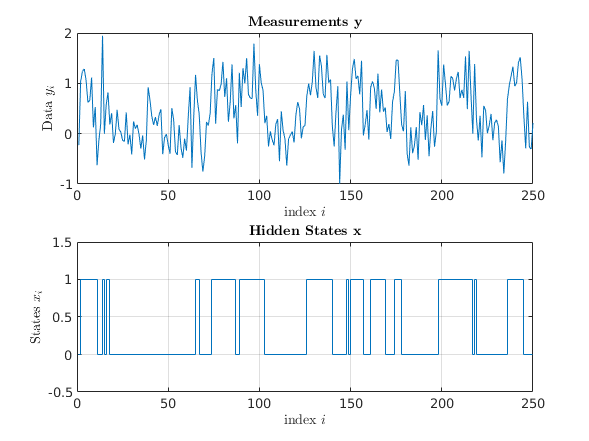

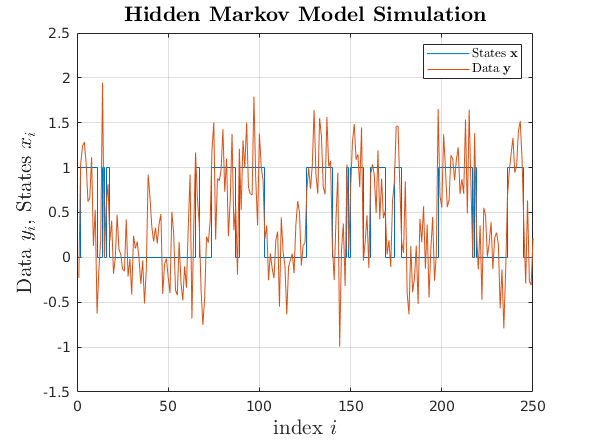

N = 250;
x_Markov = ones(N,1)*-1;
r = rand(N,1);

if r(1) < 0.5
    x_Markov(1) = 1;
else
    x_Markov(1) = 0;
end

for i = 2:N
    if r(i) < 0.9
        x_Markov(i) = x_Markov(i-1);
    else
        x_Markov(i) = 1 - x_Markov(i-1);
    end
end

noise = 0.4*randn(N,1);

y = x_Markov + noise;

plotting_a(x_Markov, y);

## B) - Forward recursion

tau = [0.15:0.01:2];
p = [0.2:0.01:0.99];

Z = zeros(length(p),length(tau));


for r = 1:length(p)
    for c = 1:length(tau)
        
        Z(r,c) = forward_reqursion( p(r), tau(c), y, N );
    
    end
end

[~,max_indx] = max(Z(:));
[r,c]=ind2sub(size(Z),max_indx);

disp("Max likelihood p = " + num2str(p(r)));

Max likelihood p = 0.89


disp("Max likelihood tau = " + num2str(tau(c)));

Max likelihood tau = 0.38


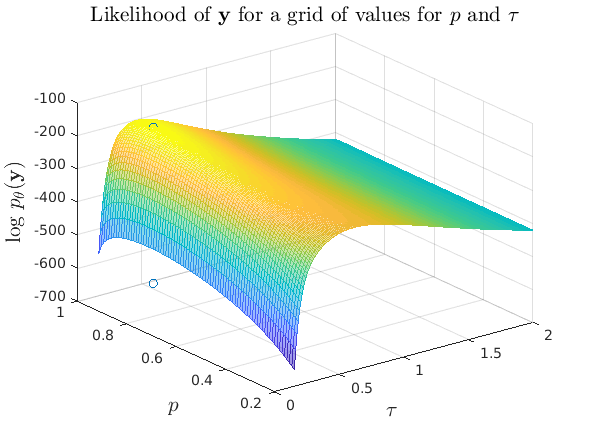

figure;
[X,Y] = meshgrid(tau,p);
mesh(X,Y,Z,'FaceAlpha',0.5,'FaceColor','interp');
hold on;
plot3([tau(c),tau(c)],[p(r),p(r)],[min(Z(:)),max(Z(:))],'o');
xlabel("$\tau$",'interpreter', 'latex', 'FontSize', 15);
ylabel("$p$",'interpreter', 'latex', 'FontSize', 15);
zlabel("$\mathrm{log} \,\, p_{\theta}(\mathbf{y})$",'interpreter', 'latex', 'FontSize', 15);
title('Likelihood of $\mathbf y$ for a grid of values for $p$ and $\tau$', 'interpreter', 'latex', 'FontSize', 15);

## C - Backward Recursion

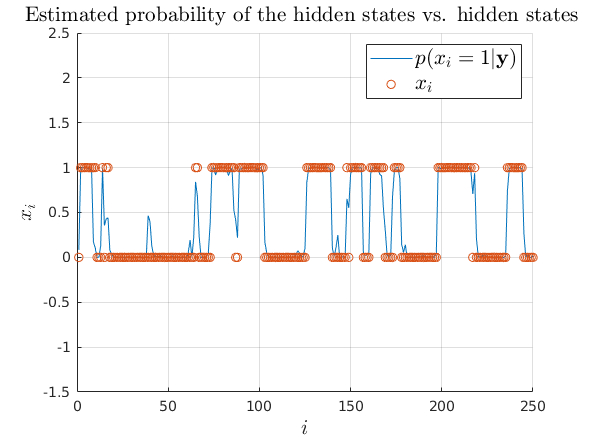

[~,prio_xY,post_xY] = forward_reqursion(0.9,0.4,y,N);
margp_xY = backward_recursion(0.9,prio_xY,post_xY,N);

figure;
hold on;
plot(margp_xY(2,:));
stairs(x_Markov,'o'); grid on;
ylabel('$x_i$', 'interpreter', 'latex', 'FontSize', 15);
xlabel('$i$', 'interpreter', 'latex', 'FontSize', 15);
legend("$p(x_i = 1|\mathbf{y})$","$x_i$",'interpreter', 'latex', 'FontSize', 15);
title('Estimated probability of the hidden states vs. hidden states ', 'interpreter', 'latex', 'FontSize', 15);
axis([0 250 -1.5 2.5]);

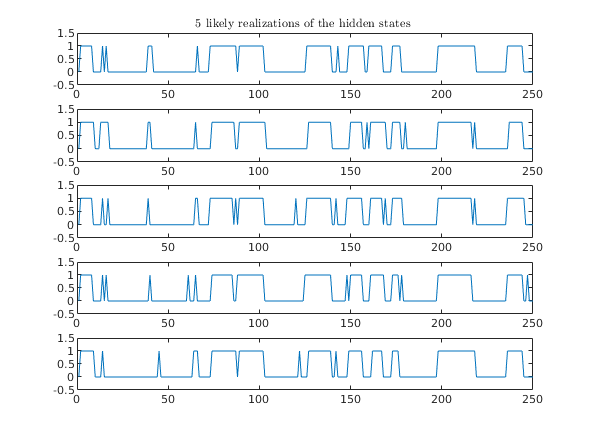


N_realisations = 5;
x_realization = zeros(N_realisations,N); 
r = rand(N_realisations,N);

figure;
for b = 1:N_realisations
    
    x_realization(b,:) = r(b,:) < margp_xY(2,:);
    
    subplot(N_realisations,1,b);
    plot(x_realization(b,:));
    if b == 1
        title('5 likely realizations of the hidden states ', 'interpreter', 'latex', 'FontSize', 15);
    end
    axis([0 250 -0.5 1.5]);
end

## D - Comparason without HMM assumption

x_Markov = zeros(1,N);
x_NoMarkov = zeros(1,N);
for i = 1:N
   if(margp_xY(2,i) >= 0.5)
       x_Markov(i) = 1;
   else
       x_Markov(i) = 0;
   end
   
   if(y(i) < 0.5)
       x_NoMarkov(i) = 0;
   else
       x_NoMarkov(i) = 1;
   end
end

figure
hold on
plot(x_NoMarkov,'o')
plot(x_Markov)
legend("No Markov","Markov")